# Small angles and our 7-dof EOM

In this Tutorial we'll review the concepts of PASSIVE rotation matrices.  We'll then look at how the **Small angle** approximation for our 7-dof TRANSVERSE car model impacts the general Moment equation for a rigid body expressed in components of a BODY fixed frame:

- 
$$M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;+\;\;\omega \times \left(I_G^B \ldotp \omega_G^B \right)$$


`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## Review the concept of PASSIVE rotation matrices :

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** by $\theta$ relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

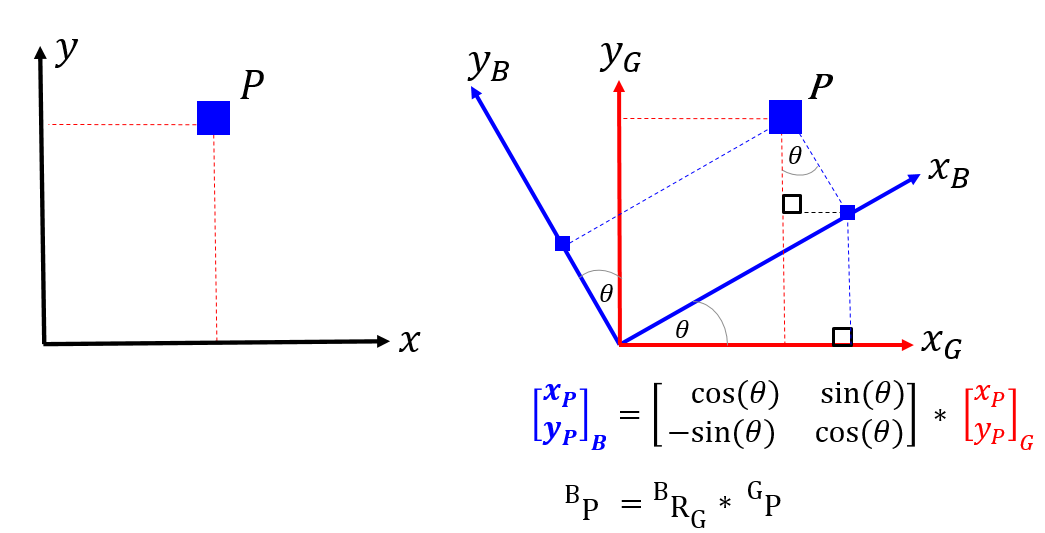 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

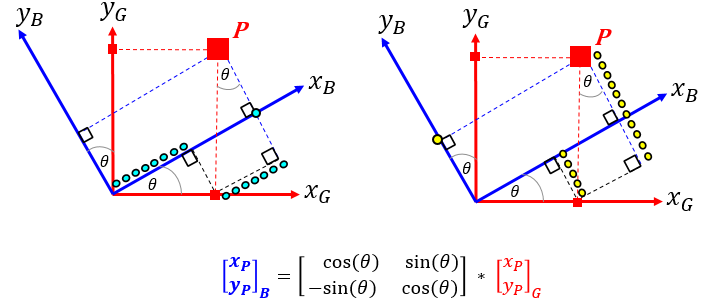

## An example of 2 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 2 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\theta)$, aka **PITCH**

- R2X occurs 2nd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:

- $\bf ^Bv = R2X(\psi_X) \enspace \times \enspace R1Z(\theta_Z) \enspace \times \enspace {^Gv}$    OR, in a more compact form as:

- 
$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


So let's get ready to explore:

clear theta          psi   
clear theta_dot      psi_dot
clear theta_ddot  psi_ddot

syms  theta          psi   
syms  theta_dot      psi_dot
syms  theta_ddot     psi_ddot

### Create a passive rotation object

OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2X'}, [theta, psi], 'SYM')

OBJ_P =   bh_rot_passive_G2B_CLS with properties:

        ang_units: SYM
    num_rotations: 2
          dir_1st: D1Z
          dir_2nd: D2X
          dir_3rd: ---
          ang_1st: [1×1 sym]
          ang_2nd: [1×1 sym]
          ang_3rd: [1×1 sym]


### Here are the PASSIVE rotation matrices:

Here's  $\bf  R1Z(\theta_Z) $:

R1Z = OBJ_P.get_R1

$$R1Z = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Here's $\bf R2X(\psi_X) $

R2X = OBJ_P.get_R2

$$R2X = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

### Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          $^{B}v  = {^{B}}R_G \times  {^{G}}v$

bRg = R2X * R1Z

$$bRg = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) & \sin\left(\psi \right)\\ \sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

### Explore the relationship between BODY rates and EULER rates

As we apply these local frame rotations of ($ \theta, \psi$), we can represent the **angular rates** ($ \dot{\theta}, \dot{\matrix{\psi}}$) of the rotating frames into the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.

 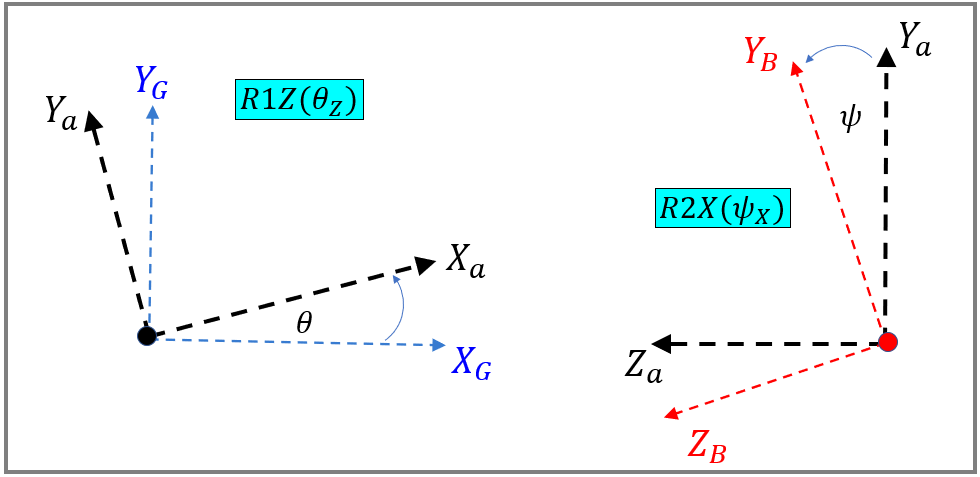

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

aRg = R1Z;
bRa = R2X;

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\theta}}$ rate:

wb_part_1 = bRa * aRg * [0;0;theta_dot]   % convert local G into B

$$wb\_part\_1 = \left(\begin{array}{c} 0\\ \dot{\theta }\,\sin\left(\psi \right)\\ \dot{\theta }\,\cos\left(\psi \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\psi}}$ rate:

wb_part_2 = bRa *       [psi_dot;0;0]   % convert local a into B

$$wb\_part\_2 = \left(\begin{array}{c} \dot{\psi }\\ 0\\ 0 \end{array}\right)$$

### The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.

- 
$$_G^{B}\omega_b \equiv \omega_b = f( \dot{ \matrix{\theta}}, \dot{ \matrix{\psi}},  \theta, \psi) $$
 

wb = wb_part_1 + wb_part_2  

$$wb = \left(\begin{array}{c} \dot{\psi }\\ \dot{\theta }\,\sin\left(\psi \right)\\ \dot{\theta }\,\cos\left(\psi \right) \end{array}\right)$$

### Small angle approximation

For small angles of $\theta$ and $\psi$ we have:

- $\sin \left(\theta \right)=\theta$   and   $\cos \left(\theta \right)=1$

- $\sin \left(\psi \right)=\psi$   and   $\cos \left(\psi \right)=1$

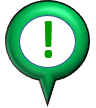**NOTE: ** So when is this Small Angle approximation correct ?  Well, as a guide:

- $\frac{\sin \left(x\right)}{x}\;\ge \;\;0\ldotp 95\;\;$  for  $-31\le x\le 31\;\left(\deg \right)$   OR      $-0\ldotp 55\le x\;\le 0\ldotp 55\;\;\left(\mathrm{radians}\right)$

- $\cos \left(x\right)\;\ge \;\;0\ldotp 95\;\;$  for  $-18\le x\le 18\;\left(\deg \right)$   OR      $\;-0\ldotp 3\le \;x\;\le 0\ldotp 3\;\;\left(\mathrm{radians}\right)$

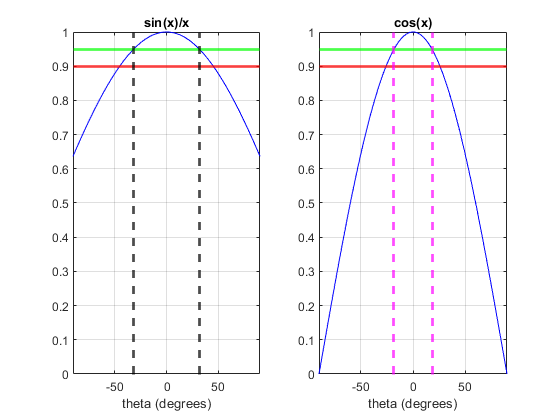

tmp_deg_domain = [-90, 90];
figure;
        subplot(1,2,1);
            fplot(@(x) sind(x)./(pi*x/180), tmp_deg_domain, '-b');
                grid("on")
                xlabel("theta (degrees)");   
                ylim([0, 1])
                hold("on")
            yline(0.95,'-g', 'LineWidth',2);
            yline(0.9 ,'-r', 'LineWidth',2);
            xline(-31.622, '--k', 'LineWidth',2);
            xline( 31.622, '--k', 'LineWidth',2);
            title("sin(x)/x")
        subplot(1,2,2);
            fplot(@(x) cosd(x), tmp_deg_domain, '-b');
                grid("on")
                xlabel("theta (degrees)");   
                ylim([0, 1])
                hold("on")
            yline(0.95,'-g', 'LineWidth',2);
            yline(0.9 ,'-r', 'LineWidth',2);
            xline(-18.195, '--m', 'LineWidth',2);
            xline( 18.195, '--m', 'LineWidth',2);
            title("cos(x)")            

So our angular velocity vector becomes:

wb_small_ang = subs(wb,[sin(theta), sin(psi), cos(theta), cos(psi)],[theta, psi,1,1])

$$wb\_small\_ang = \left(\begin{array}{c} \dot{\psi }\\ \psi \,\dot{\theta }\\ \dot{\theta } \end{array}\right)$$

If we continue with the simplification, we may regard the term $\left(\psi \ldotp \dot{\theta} \right)$ as "small" in comparison to $\dot{\theta}$ and $\dot{\psi}$  .... and therefore assume that $\left(\psi \ldotp \dot{\theta} \right)$ is zero (can be neglected).

wb_small_ang(2) = 0

$$wb\_small\_ang = \left(\begin{array}{c} \dot{\psi }\\ 0\\ \dot{\theta } \end{array}\right)$$

## Impact on our Body fixed Newton Moment equation

Recall the well known Moment equation for a rigid body expressed in components of a BODY fixed frame:

- 
$$M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;+\;\;\omega \times \left(I_G^B \ldotp \omega_G^B \right)$$


syms I_X  I_Z  I_Y
syms M_X  M_Y  M_Z

Assume the BODY fixed frame is aligned with the body's principal axes:

M = [M_X ; M_Y ; M_Z  ];
I = [ I_X,    0,   0;
        0,  I_Y,   0;
        0,    0, I_Z  ];

wb_dot = [psi_ddot;0;theta_ddot];
w      = wb_small_ang;

EQ = M == I*wb_dot  + cross(w, I*w)

$$EQ = \left(\begin{array}{c} M_{X}=I_{X}\,\ddot{\psi }\\ M_{Y}=I_{X}\,\dot{\psi }\,\dot{\theta }-I_{Z}\,\dot{\psi }\,\dot{\theta }\\ M_{Z}=I_{Z}\,\ddot{\theta } \end{array}\right)$$

So if our interest is only on the $Z$ and $X$ axes, we have:

EQ([1, 3])

$$ans = \left(\begin{array}{c} M_{X}=I_{X}\,\ddot{\psi }\\ M_{Z}=I_{Z}\,\ddot{\theta } \end{array}\right)$$

### Conclusion  - Part 1

Our Small angle assumption means that we can write our Body Fixed Moment equations in a VERY VERY simple (and Familiar form), ie:

- 
$$M_X \;\;=\;I_X \ldotp \ddot{\psi}$$


- 
$$M_Z \;\;=\;I_Z \ldotp \ddot{\theta}$$


### Now regarding the computations of moments:

bRg_small = subs(bRg      ,[sin(theta), sin(psi), cos(theta), cos(psi)],[theta, psi,1,1])

$$bRg\_small = \left(\begin{array}{ccc} 1 & \theta & 0\\ -\theta & 1 & \psi \\ \psi \,\theta & -\psi & 1 \end{array}\right)$$

bRg_small = subs(bRg_small, theta*psi, 0)

$$bRg\_small = \left(\begin{array}{ccc} 1 & \theta & 0\\ -\theta & 1 & \psi \\ 0 & -\psi & 1 \end{array}\right)$$

Vertical vectors in the INERTIAL G frame(say in the $Y^G$ direction) are converted into the following components in the BODY fixed frame:

syms F
F_b = bRg_small * [0;F;0]

$$F\_b = \left(\begin{array}{c} F\,\theta \\ F\\ -F\,\psi \end{array}\right)$$

Which if we again exercise the small angle assumption we conclude that $0\approx F\ldotp \theta$ and $0\approx F\ldotp \psi$

F_b_small = subs(F_b, [theta,psi], [0,0])

$$F\_b\_small = \left(\begin{array}{c} 0\\ F\\ 0 \end{array}\right)$$

So a moment  computed in the BODY fixed frame would be

syms x1 y1 z1

M_Z = cross([x1;y1;z1], F_b_small)

$$M\_Z = \left(\begin{array}{c} -F\,z_{1}\\ 0\\ F\,x_{1} \end{array}\right)$$